# 4. Semesterproject

% Settings
sympref('MatrixWithSquareBrackets',true)

ans = logical
   1


## Declaring variables for the two systems

### Cart

clc; clear;
syms x              % [m]       position 
syms x_dot_c        % [m/s]     velocity
syms x_ddot_c       % [m/s^2]   acceleration
syms T_c            % [N]       tension force
syms F_c            % [N]       external force

m_c = 0.5           % [Kg]      mass of cart

m_c = 0.5000

b_c = 5             % [N/(m/s)] damping coefficient, cart

b_c = 5

g = 9.82            %           gravity coefficient

g = 9.8200

F_gc = m_c*g        %           gravity for cart

F_gc = 4.9100

F_n = F_gc          %           normal force

F_n = 4.9100

F_dc = b_c*x_dot_c

$$F\_dc = 5\,{\dot{x}}_{c}$$

### Pendulum

syms theta             % [rad]     angle of pendulum
syms theta_dot         % [rad/sec] angle velocity
syms theta_ddot        % [rad/sec^2] angle acceleration
syms tau_e             % [Nm]      external torque
syms t_p               %           tension of pendulum
syms F_dist            % [N]       disturbance force
syms F_gp              % [N]       gravity of pendulum


m_p = 0.084            % [Kg]      mass of the pendulum

m_p = 0.0840

m_rod = 0.082          % [Kg]      mass of the rod

m_rod = 0.0820

m_wa = 0.002           % [Kg]      mass of the weight attached

m_wa = 0.0020

l_rod = 0.35           % [m]       length of rod

l_rod = 0.3500

l_p = (m_rod*(l_rod/2)+m_wa*l_rod)/(m_rod+m_wa)         % [m] length to center of mass

l_p = 0.1792

b_p = 0.0012                                            % [N/(m/s)] damping coefficient, pendulum

b_p = 0.0012

F_dp = b_p*theta_dot                                    % [N] damping force of pendulum

$$F\_dp = \frac{3\,\dot{\theta }}{2500}$$

h = l_p*cos(theta)                                      % [m] height of pendulum/ y component

$$h = \frac{43\,\cos\left(\theta \right)}{240}$$

## Linearized Differential equations, for $\ddot{x_c } \;,\ddot{\theta}$


$$\ddot{x_c } =\frac{F_c }{m_c }-\frac{b_c }{m_c }\cdot \dot{x_c } -\frac{b_p }{m_c \cdot l_p }\cdot \dot{\theta} +\frac{m_p \cdot g}{m_c }\cdot \theta$$


x_ddot_c = (F_c/m_c)-(b_c/m_c)*x_dot_c-(b_p/(m_c*l_p))*theta_dot+((m_p*g)/(m_c))*theta

$$x\_ddot\_c = 2\,F_{c}+\frac{10311\,\theta }{6250}-\frac{72\,\dot{\theta }}{5375}-10\,{\dot{x}}_{c}$$


$$\ddot{\theta} =-\frac{b_p }{m_p \cdot l_p^2 }\cdot \frac{m_c +m_p }{m_c }\cdot \dot{\theta} +\frac{F_c }{m_c \cdot l_p }-\frac{b_c }{m_c \cdot l_p }\cdot \dot{x_c } +\frac{g}{l_p }\cdot \frac{m_c +m_p }{m_c }\cdot \theta$$


theta_ddot = -(b_p/(m_p*l_p^2))*((m_c+m_p)/m_c)*theta_dot+(F_c/(m_c*l_p))-(b_c/m_c*l_p)*x_dot_c+(g/l_p)*((m_c+m_p)/m_c)*theta

$$theta\_ddot = \frac{480\,F_{c}}{43}+\frac{281550909495071\,\theta }{4398046511104}-\frac{2340939283092633\,\dot{\theta }}{4503599627370496}-\frac{43\,{\dot{x}}_{c}}{24}$$

## State space model


$$\dot{x_{\textrm{state}} } =\frac{d}{\textrm{dt}}\left\lbrack x_{\textrm{state}} \right\rbrack =\left\lbrack \begin{array}{c}
\dot{x_c } \\
\ddot{x_c } \\
\dot{\theta} \\
\ddot{\theta} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & -\frac{b_c }{m_c } & \frac{m_p \cdot g}{m_c } & -\frac{b_p }{m_c \cdot l_p }\\
0 & 0 & 0 & 1\\
0 & -\frac{b_c }{m_c \cdot l_p } & \frac{g}{l_p }\cdot \frac{m_c +m_p }{m_c } & -\frac{b_p }{m_p \cdot l_p^2 }\cdot \frac{m_c +m_p }{m_c }
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
x_c \\
\dot{x_c } \\
\theta \;\\
\dot{\theta \;} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{m_c }\\
0\\
\frac{1}{m_c \cdot l_P }
\end{array}\right\rbrack \cdot F_c$$


A = [0 1 0 0; 0 -(b_c/m_c) (m_p*g)/m_c -(b_p/(m_c*l_p)); 0 0 0 1; 0 -(b_c/(m_c*l_p)) (g/l_p)*((m_c+m_p)/m_c) -(b_p/(m_p*l_p^2))*((m_c+m_p)/m_c)]

A =          0    1.0000         0         0
         0  -10.0000    1.6498   -0.0134
         0         0         0    1.0000
         0  -55.8140   64.0173   -0.5198


B = [0; 1/m_c; 0; 1/(m_c*l_p)]

B =          0
    2.0000
         0
   11.1628


C = [1 0 0 0; 0 0 0 0; 0 0 1 0; 0 0 0 0] % cart position, pendul angle

C =      1     0     0     0
     0     0     0     0
     0     0     1     0
     0     0     0     0


D=0;


% prompt = (['What output do you want?: ' newline...
%     '1 = cart position: ' newline...
%     '2 = cart velocity: ' newline...
%     '3 = pendulum angle: ' newline...
%     '4 = pendulum angle velocity: ' newline...
%     '5 = show all: ' newline...
%     'else a default C is defined, cart position and pendulum angle' newline]) 
% input = input(prompt)
% switch(input)
%     case 1
%         fprintf('cart position')
%         C =[1 0 0 0]
%     case 2
%         fbprintf('cart velocity')
%         C = [0 1 0 0]
%     case 3
%         fprintf('pendulum angle')
%         C = [0 0 1 0]
%     case 4
%         fprintf('pendulum angle velocity')
%     case 5 
%         fprintf('show All, C_general')
%         C = eye(4)   % Shows all pos, and velocities, just for test. 
%     otherwise
%         fprintf('Cart pos, pendulum angle')
%         C = [1 0 0 0; 0 0 0 0; 0 0 1 0; 0 0 0 0]    % C for cart pos, and pendulum angle
% end

sys= ss(A,B,C,D)

sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0      -10     1.65  -0.0134
   x3        0        0        0        1
   x4        0   -55.81    64.02  -0.5198
 
  B = 
          u1
   x1      0
   x2      2
   x3      0
   x4  11.16
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   0   0
   y3   0   0   1   0
   y4   0   0   0   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



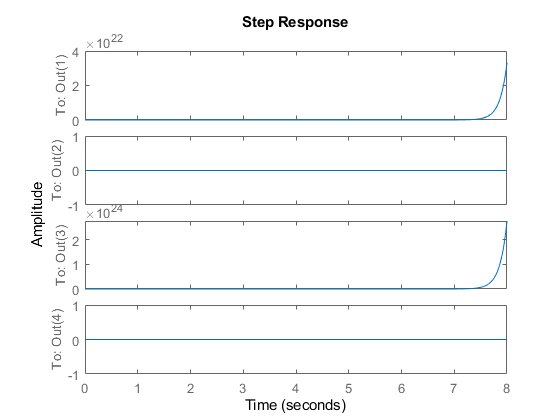

step(sys)

% [num,denum]=ss2tf(A,B,C,D); % Error if case 5 is choosen
%TF_sys = tf(num,denum)
%pzmap(TF_sys)

% Is the dynamics stable? No, we have a val in the rihgt side of the plane
eigenval = eig(A)

eigenval =          0
  -11.5752
   -6.3737
    7.4291


## Classic Control System Design - Analyse

C_angle = [0 0 1 0]

C_angle =      0     0     1     0


sys_pendulum = ss(A,B,C_angle,D)

sys_pendulum =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0      -10     1.65  -0.0134
   x3        0        0        0        1
   x4        0   -55.81    64.02  -0.5198
 
  B = 
          u1
   x1      0
   x2      2
   x3      0
   x4  11.16
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



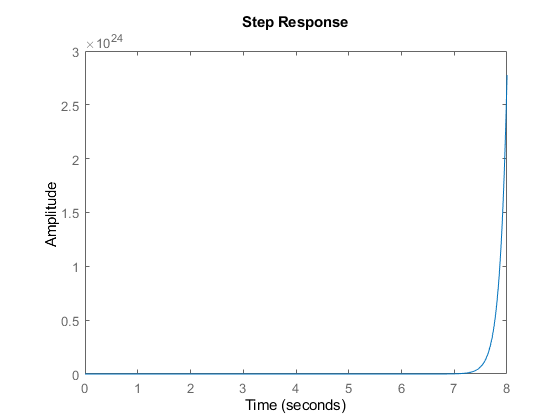

step(sys_pendulum)

[num,denum] = ss2tf(A,B,C_angle,D)

num =          0         0   11.1628    0.0000    0.0000


denum =     1.0000   10.5198  -59.5670 -548.0930         0


G_pend = tf(num,denum)

G_pend =
 
   11.16 s^2 + 1.901e-14 s + 2.744e-15
  -------------------------------------
  s^4 + 10.52 s^3 - 59.57 s^2 - 548.1 s
 
Continuous-time transfer function.



step(G_pend)

Noter: System er ustabilt

Udkast til nogle krav:

- Settelingtime : less than 3 sec

- $\alpha %$: Pendulun should not move more than 5 degrees $\approx 0\ldotp 087\;\textrm{radians}$

- Max overshoot, t_p på 45 grader $\approx 0\ldotp 7854$. (svær at rede)

- rise time 1 sec

### Udregning af specifikationer

hint: lektion 5, slide 13 og 18

% Specs
t_r = 1         % [Seconds] Rise time

t_r = 1

t_s = 3         % [Seconds] 

t_s = 3

M_p = pi/4      % [Radians] Overshoot, i ikke procent

M_p = 0.7854

alpa = 0.08     % Alpha værdi, have divide with 100

alpa = 0.0800


% Beregner
w_n = 1.8/t_r   % [Hz] udæmpet naturlige frekvens

w_n = 1.8000

zeta = sqrt(((log(M_p)/-pi)^2)/(1+((log(M_p))/-pi)^2))  % [Radians] overshoot smaller than M_p

zeta = 0.0767

sigma = 4.6/t_s

sigma = 1.5333

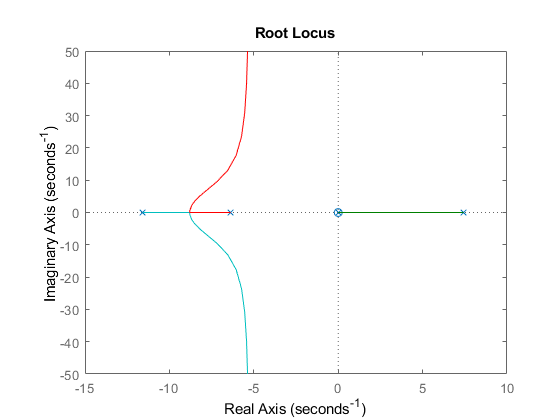


rlocus(G_pend) % Får en pol i højre siden 

% Cp =[0 0 1 0]
% sysPend= ss(A,B,Cp,D)
% PendController = pidtune(sysPend, 'PIDF')